# Reading .RAW file

## Raw files were created in VS in C

Opening the file

clear
Raw_data_on = fopen("Unprocessed Data\3.25.22\65534 shots.raw");
% Raw_data_on = fopen("Unprocessed Data\pump_off_start.raw"); % no white light
% Raw_data_off = fopen("Unprocessed Data\pump_on_start.raw"); % no white light
%Raw_data = fopen("Image_1.raw"); % no white light
%Raw_data = fopen("Image_1_2021.10.01_123436.raw"); % no spectrometer
%Raw_data = fopen("Image_1_2021.10.15_152913.raw");

%Image = readmatrix("Unprocessed Data\test_data_2.23.22_trigmode4.csv");

Reading the file

ImageOn = fread(Raw_data_on,'uint16');
% ImageOff = fread(Raw_data_off,'uint16');

Creating the dimensions and size of image

dim_Image = size(ImageOn,1);
Image_xsize = 2048;
Image_ysize = dim_Image/Image_xsize;
ImageOn = reshape(ImageOn, Image_xsize, Image_ysize);
ImageOn = ImageOn'

ImageOn =     62    62   110   109   109   106   109   108   104   106   102   104   108   104   104   105   100    98   100   103   100    97    99    97    96    97    95    91    96    96    91    90    88    92    88    93    87    85    88    86    87    87    83    82    80    79    81    84    80    81
    61    64   109   109   111   107   107   107   105   107   103   106   109   109   107   107   104   100    99   100   101    94    98    98    99    96    94    92    97    95    94    92    90    90    91    93    87    89    88    84    84    87    83    81    82    83    84    85    83    86
    62    63   105   107   110   107   109   107   107   109   103   104   109   105   104   103    98   100   102    98    97    98    95    99    95    94    91    92    95    97    91    93    88    90    89    91    88    85    84    86    86    84    82    82    84    81    81    82    80    80
    58    63   106   108   108   108   105   105   104   106   106   103   108   107   

% ImageOff = reshape(ImageOff, Image_xsize, Image_ysize);
% ImageOff = ImageOff'

Creating the image

% imagesc(Image')
% ylabel('Row');
% xlabel('Column');
% colorbar

Putting the data into a 2D array

%Image_arr = Image';
%Image_arr = Image;
% a = Image_arr(:,2046:2048); % last 2 columns
% b = Image_arr(:, 1:2);  % first 2 columns

Concatinate rows to plot average value of each pixel

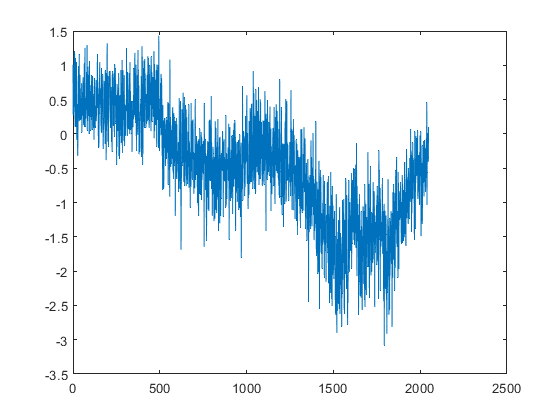

% avg_val = mean(Image_arr);
pixel = linspace(0,2048,2048);

% var(avg_val)
% plot(pixel,avg_val)
% title("Average Pixel Values for 1000 Shots")
% xlabel("pixel position")
% ylabel("avg value")

on_on_shots = ImageOn(1:2:end,:);
on_off_shots = ImageOn(2:2:end,:);

% off_off_shots = ImageOff(1:2:end,:);
% off_on_shots = ImageOff(2:2:end,:);

Mon = on_on_shots - on_off_shots;
%DTTon = Mon./on_off_shots;
avg_shots_on = mean(Mon);

% Moff = off_on_shots - off_off_shots;
%DTToff = Moff./off_off_shots;
% avg_shots_off = mean(Moff);

% %avg_even_shots = mean(even_shots);
% 
plot(pixel, avg_shots_on); % hold on;

% plot(pixel, avg_shots_off); legend ("on","off");hold off;

% newplot
% noise = avg_shots_on+avg_shots_off;
% plot(noise)

% hold on
% plot(pixel, avg_even_shots)
% legend("odd shots", "even shots")
% xlabel('pixel position')
% ylabel('value')
% hold off

Pixel #490 over 1000 lines/shots

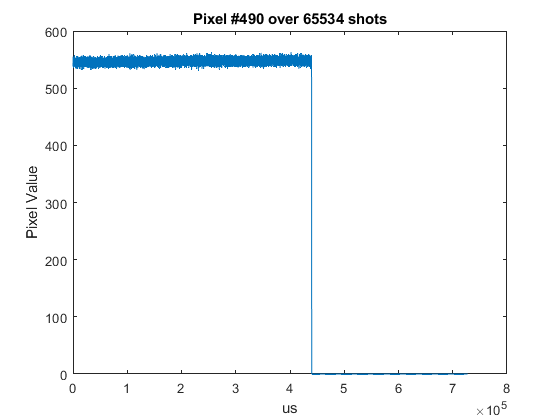

pxl490 = ImageOn(:,490);
duration = 11.1*65534;
time_steps = linspace(0, duration, 65534);
% 
% % saving the data in csv file - to compare using python
% %writematrix(pxl490, "WL_pxl490_10.15.2021.csv")
% 
plot(time_steps, pxl490)
title("Pixel #490 over 65534 shots")
ylabel("Pixel Value")
xlabel("us")

Variance and Covariance

% %Variance
% var(pxl490)
% std(pxl490)

Autocorrelation of single pixel over time (pixel #490)

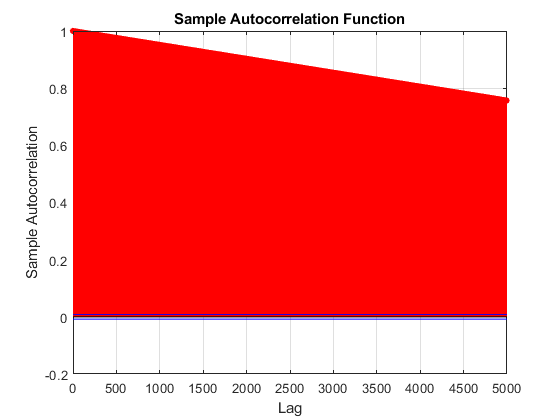

% %[row, col] = find(isnan(pxl490))
% %if there are no NaN values in the vector why is there lag in the autocorr
autocorr(pxl490, "NumLags", 5000)

% %plot(autocorr(pxl490,"NumLags",999))
% plot(autocorr(pxl490,"NumLags",50))
% title("Autocorrelation map of pixel 490")
% 
% [acf, lags, bounds] = autocorr(pxl490);
% acf;
% lags;
% bounds;

Autoorrelation of single pixel over time with odd shots and even shots taken seperately

% pxl490_odd = (pxl490(1:2:end,:));
% var(pxl490_odd)
% std(pxl490_odd)
% pxl490_even = (pxl490(2:2:end,:));
% var(pxl490_even)
% std(pxl490_even)
% 
% ac_pxl490_odd = autocorr(pxl490_odd,"NumLags",50);
% %pc_pxl490_odd = parcorr(pxl490_odd,"NumLags",100)    
% ac_pxl490_even = autocorr(pxl490_even,"NumLags",50);
% %pc_pxl490_even = parcorr(pxl490_even,"NumLags",100)
% 
% autocorr(pxl490_odd,"NumLags",50)
% plot(ac_pxl490_odd)
% title("Autocorr of pixel 490 (odd shots)")
% autocorr(pxl490_even,"NumLags",50)
% plot(ac_pxl490_even)
% title("Autocorr of pixel 490 (even shots)")
% 

% %corr_matrix = corr(Image)
% %imagesc(corr_matrix)
% %colorbar
% %plot(diag(pixel,corr_matrix))
% %title("Correlation map of each pixel over 11.11 ms")